# State Feedback Control Using State Estimator 

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

 In Modules 3 and 4, we derived fixed gain state feedback laws of the form $u(k)=-Gx(k)$ for unconstrained finite horizon MPC formulation and for the infinite horizon LQOC. While developing these control laws, it was assumed that the state is perfectly measured. In practice, however, *perfect state measurement* is an unrealistic assumption. In the previous module, we developed state estimators that construct an estimate of the state sequence $\left\lbrace \hat{x} \left(k\right):k=1,2,\ldotp \ldotp \ldotp \right\rbrace$ starting from some initial guess $\widehat{x} \left(0\right)$ and the measurement sequence $\left\lbrace y\left(j\right):j=1,2,\ldotp \ldotp \ldotp \ldotp \right\rbrace$. In this lesson we illustrate how the estimated state sequence can be used for implementation of the state feedback control laws. 

**Learning objectives** are: 

- Carry out the nominal stability analysis of state feedback control law implementation using a state estimator 

- Investigate effect of unmeasured disturbances and model plant mismatch on closed loop behavior under state feedback regulator 

- Modify state feedback regulator by introducing moving target states and target inputs for dealing with unmeasured disturbances and model plant mismatch 

## Nominal Stability Analysis: Separation Principle 

 As stated earlier, the **nominal stability analysis** refers to analyzing the stability of a system **under its nominal (ideal or expected) conditions**, i.e., **without considering uncertainties**, disturbances, or modeling errors.   Let us assume that the system system dynamics are governed by the ideal discrete time linear model

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)$   -------------(1)

 In Modules 3 and 4, we derived fixed gain state feedback laws of the form $u(k)=-Gx(k)$ for unconstrained finite horizon MPC formulation and for the infinite horizon LQOC.  In the case of finite horizon unconstrained MPC controller, the nominal stability had to be established by finding eigenvalues of $\left(\Phi -\Gamma G_{\textrm{MPC}} \right)$. Using Lyapunov's second method, it was shown that the infinite horizon LQOC guarantees closed loop stability and all eigenvalues of $\left(\Phi -\Gamma G_{\infty } \right)$ are strictly inside the unit circle if the system is reachable.

 In the [previous module](matlab:open('../6. State_Estimation for MPC/L01_IntroductiontoStateEstimation.mlx')), we developed state estimators of the from 

$\hat{x\;} \left(k+1\right)=\Phi \widehat{x} \left(k\right)+\Gamma u\left(k\right)+Le\left(k\right)$---------(2)

$e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$--------(3)

 that construct an estimate of the state $\hat{x} \left(k\right)$ starting from some initial guess $\widehat{x} \left(0\right)$ and the measurement sequence $\left\lbrace y\left(j\right):j=1,2,\ldotp \ldotp \ldotp \ldotp \right\rbrace$. Here, $L$ represents the observer gain matrix. The nominal stability of the estimator error dynamics is guaranteed when $\rho \left(\Phi -LC\right)<1$ where $\rho \left(\ldotp \right)$ denotes the spectral radius of the matrix in brackets. In particular, the steady state Kalman gain matrix, $L=L_{\infty }$, was found by solving the algebraic Riccati equations. Subsequently, using Lyapunov's second method, we also established that eigenvalues of $\left(\Phi -{\mathrm{L}}_{\infty } \;C\right)$ are strictly inside the unit circle if the system is observable. 

Since$x\left(k\right)$ is not known exactly, we implement the state feedback control law using the estimated state, i.e. $u\left(k\right)=-G\hat{x} \left(k\right)$. Thus, the closed loop dynamics are governed by the 

$x\left(k+1\right)=\Phi x\left(k\right)-\Gamma G\;\hat{x} \left(k\right)=\left(\Phi -\Gamma G\right)x\left(k\right)+\Gamma G\;\varepsilon \left(k\right)\;$   -------------(4)

where $\varepsilon \left(k\right)=\left(x\left(k\right)-\hat{x} \left(k\right)\right)$ represents the state estimation error. Subtracting equation (2) from (1), we can show that the estimation error evolves as

 $\varepsilon \left(k+1\right)=\left(\Phi -L\;C\right)\varepsilon \left(k\right)$   ------(5)

Thus, the nominal closed loop system now evolves as the following unforced system 

$\left\lbrack \begin{array}{c}
x\left(k+1\right)\\
\varepsilon \left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
\left(\Phi -\Gamma G\right) & \Gamma G\\
\left\lbrack 0\right\rbrack  & \left(\Phi -LC\right)
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\left(k\right)\\
\varepsilon \left(k\right)
\end{array}\right\rbrack$    ------(6) 

It is easy to show that the characteristic equation of the closed loop matrix is

 $\det \left(\lambda I-\left(\Phi -\Gamma G\right)\right)\;\det \left(\lambda I-\left(\Phi -L\;C\right)\right)=0$   ------(7)

Note that any state feed back control law is designed such that $\rho \left(\Phi -\Gamma G\right)<1\;\;\textrm{and}\;$any observer designed such that $\rho \left(\Phi -L\;C\right)<1$ . Equation (7) tells us that, if the controller and observer are separately designed to be nominally stable, then their combination gives rise to a nominally stable closed loop systems. This is referred to as the ***separation principle***.  In fact, when if we choose $G=G_{\infty }$ and $L=L_{\infty } ,$ the nominal closed loop stability is guaranteed together with performance as eigenvalues of  $\left(\Phi -\Gamma G_{\infty } \right)$ and $\left(\Phi -{\mathrm{L}}_{\infty } \;C\right)$ are strictly inside the unit circle. Thus,  combination of LQR and steady state Kalman filter give rise to a closed loop system with guaranteed nominal stability. 

### Example: Reactor at Unstable Operating Point 

Now, let is look at another example: Continuous Stirred Tank Reactor (CSTR) system operated at the unstable operating point. The system dynamics are governed by the following


$$\left\lbrack \begin{array}{c}
{\delta C}_A \left(k+1\right)\\
\delta T\left(k+1\right)
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
0\ldotp 7943 & -0\ldotp 006245\\
11\ldotp 93 & 1\ldotp 256
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta C}_A \left(k\right)\\
\delta T\left(k\right)
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0\ldotp 001006 & 0\ldotp 09613\\
-0\ldotp 3673 & -3\ldotp 612
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
{\delta F}_C \left(k\right)\\
\delta F\left(k\right)
\end{array}\right\rbrack$$


Here, ${\delta C}_A \;\textrm{and}\;\delta T$ represent perturbations in concentration of reactant A and temperature, respectively. Manipulated inputs,  ${\delta F}_C \;\textrm{and}\;\delta F$represent coolant flow to the cooling jacket and flow of the reactant at the reactor inlet, respectively. 

#### Closed Loop Simulation

To observe the results of closed loop simulations for implementation of LQR based on SS KF, press Run This Section Button.

 
clear all 
close all 
clc

% System matrices at the unstable operating condition 
phy=[0.7943 -0.006245 ; 11.93 1.256]; 
gam=[0.001006 0.09613; -0.3673 -3.612]';

C_mat = [ 0 1 ] ; 
samp_T = 0.1 ; 

[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
gam_d = eye(n_st) ;
[nx, n_d] = size(gam_d) ;

** rho_phy** is the maximum of absolute eigen value of $\Phi$ matrix. Both the eigenvalues lie outside the unit circle as  and the equilibrium point is unstable.

eig_val = eig(phy) ;
rho_phy = max(abs(eig_val)) 

rho_phy = 1.0354

Now we design LQOC. Let us select the following weighting matrices 

 
$$W_x =\left\lbrack \begin{array}{cc}
10 & 0\\
0 & 1
\end{array}\right\rbrack$$
  
$$W_u =\left\lbrack \begin{array}{cc}
5 & 0\\
0 & 50
\end{array}\right\rbrack$$


The LQR gain obtained is

% MPC Tuning Parameters
Wx = diag( [ 10 1 ] ) ;    % State weighting matrix  
Wu =  50 * diag( [0.1  1]) ;     % Input weighting matrix
[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wx, Wu, zeros(n_st,n_ip)) ;
G_inf

G_inf =     0.3157    0.0279
   -1.9358   -0.1157


This gain is used in computing the control inputs. While applying them to the CSTR system, they are clipped between the upper and lower bounds, if they exceed them.For the CSTR system input flows are bound between 0 and 30 for coolant flow and 0 to 2 for reactant flow. Thus, bounds on perturbation inputs, with reference to $U_s ={\left\lbrack \begin{array}{cc}
3 & 3
\end{array}\right\rbrack }^T$can be defined as follows 

$u_H =\left\lbrack \begin{array}{c}
30\\
2
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack \;$  and $u_L =\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
15\\
1
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
-15\\
-1
\end{array}\right\rbrack$

We have written a code that  generates matrices needed for specifying these input constraints. 

u_H = [30 2]' - [ 15 1]' ;  % Flow Input bounds 
u_L = [0 0]' - [ 15 1 ]' ;  % Steady state inputs are [15 1] 


** Kalman predictor design **

 Let us now check the [observability](matlab:open('../6. State_Estimation for MPC/L01_IntroductiontoStateEstimation.mlx')) of the system. The observability matrix and rank are displayed below

Q_mat = diag([0.01^2 0.2^2]) ;
R_mat = 0.15^2 ;
n_d = 2 ;
CSTR_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), samp_T ) ;

obsv_mat = obsv( phy, C_mat ) 

obsv_mat =          0    1.0000
   11.9300    1.2560


 Ro=rank(obsv_mat)

Ro = 2

As the rank of observability matrix is 2, which is equal to the number of states, we can design an observer. Here Kalman predictor is designed using MATLAB command [kalman](https://in.mathworks.com/help/control/ref/ss.kalman.html?websocket=on#mw_3ba98894-fd69-40c7-812d-569904ed6fd4)

 [KEST,L_inf,P_inf] = kalman(CSTR_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 disp('Kalman gain is')

Kalman gain is


 L_inf

L_inf =     0.0068
    1.2147


We check the stability of the observer by verifying the condition $\rho \left(\Phi -\textrm{LC}\right)<1$

 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

rho_obs = 0.4336

As the eigenvalues lie inside unit circle, the observer is stable.

**Closed loop simulations**

 N = 151 ;      % Simulation run time
 xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) =  [ 0.2 -4 ]';
uk = zeros(n_ip,N) ;

**Task: **We can either assume that all the states are measured, in that case estimator_on is set to **No**, meaning that we do not need a state estimator for state estimation. For this case, the controller inputs are obtained as

 
$$u\left(k\right)=-G\;x\left(k\right)$$


If complete state variable is not measured, then we estimate the state by making the variable estimator_on to Yes. In this case the control law is

 
$$u\left(k\right)=-G\hat{x} \left(k\right)$$


Let us select the** estimator_on flag** as **Yes**

estimator_on =1  ; % Set this to zero to use perfect state measurement 

for k = 1:N-1
    kT(k) = (k-1);

    if (estimator_on )
        uk(:,k) = - G_inf * xkhat(:,k);
        ek = yk(:,k) - C_mat * xkhat(:,k) ;
        xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
        est_err(:,k) = xk(:,k) - xkhat(:,k) ;
    else
        uk(:,k) = - G_inf * xk(:,k) ;
    end

    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end
 
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ;
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ; 


** Display Simulation Results: CSTR Unstable Equilibrium Point **

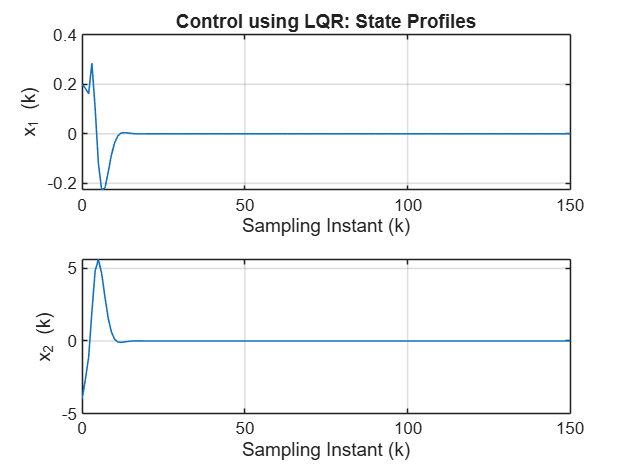

figure(1), subplot(211), plot(kT, xk(1,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('x_1 (k)')
title('Control using LQR: State Profiles')
figure(1), subplot(212), plot(kT, xk(2,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('x_2 (k)')

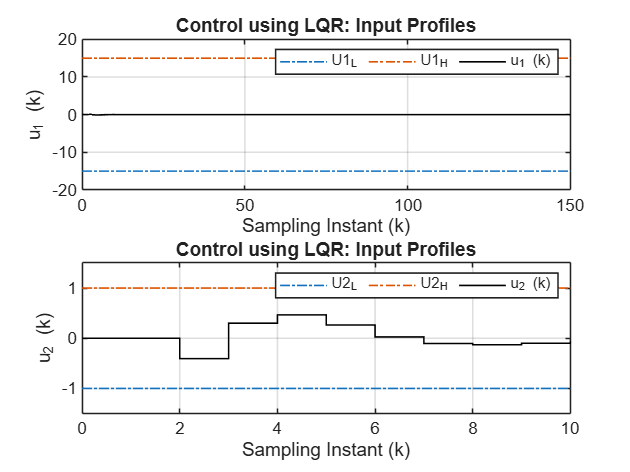

% Plot Inputs 
U1_mimits = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;
U2_mimits = [u_L(2)*ones(N,1) u_H(2)*ones(N,1)]  ;
figure(2), subplot(211), stairs(kT, U1_mimits, '-.', 'LineWidth',1), grid
hold on 
stairs(kT, uk(1,:)', 'k', 'LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_1 (k)'), title('Control using LQR: Input Profiles')
legend( 'U1_L', 'U1_H', 'u_1 (k)', 'Orientation','horizontal')
figure(2), subplot(212), stairs(kT, U2_mimits, '-.', 'LineWidth',1), grid
axis([0 10 -1.5 1.5])
hold on 
stairs(kT, uk(2,:)', 'k','LineWidth',1)
hold off
xlabel('Sampling Instant (k)'), ylabel('u_2 (k)'), title('Control using LQR: Input Profiles')
legend( 'U2_L', 'U2_H', 'u_2 (k)', 'Orientation','horizontal')

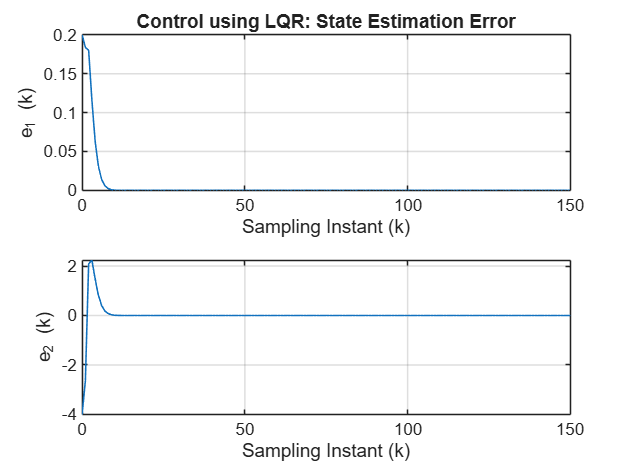

figure(3), subplot(211), plot(kT, est_err(1,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('e_1 (k)')
title('Control using LQR: State Estimation Error')
figure(3), subplot(212), plot(kT, est_err(2,:)'), grid
xlabel('Sampling Instant (k)'), ylabel('e_2 (k)')

Thus we can see that the open loop unstable system is controlled using LQR, which is designed using the estimated states by Kalman Filter. Now we can see example of designing state feedback controller based on KF for Q tank process.

### Example: Q-Tank 

Users can press the Run This section button to see the results of closed loop simulation of LQR with SS KF on Q Tank process.

 
clear all
clc
global QTank U_k D_k  % Define global variables for quadruple tank 

Set_Graphics_Parameters ;

N = 150 ; 

**Task 1**: Select the operating point for Q Tank process.  Set it as Non-minimumphase

operating_pt=2;

% Load quadruple tank parameters and steady state 
% The following file loads QTank data structure 
if operating_pt==1
load QTank_MinPhase_Model
else
 load QTank_NonMinPhase_Model 
end

% load QTank_NonMinPhase_Model 

% Quadruple tank System: Non-Minimum phase operating point 
phy= QTank.phy ;  
gam = QTank.gama_u ;
gam_d = QTank.gama_d ; 
C_mat = [1 0 0 0 ; 0 1 0 0]  ; % Levels h(1) and h(2) are measured in quadruple tank 
[n_op, nx ] = size(C_mat)  ;
[n_st, n_ip] = size(gam) ;
[nx, n_d] = size(gam_d) ;

u_H = [5 5]' - QTank.Us ;  % Physical Input bounds low are 0 and 5 Volts 
u_L = [0 0]' - QTank.Us ;  % Steady state inputs are [3 3] 

QT_sys = ss(phy, [gam gam_d], C_mat, zeros(n_op,n_ip+n_d), QTank.samp_T ) ;
Q_mat = 0.0025 ;
R_mat = QTank.R_mat ;

**Task 2:**  LQOC tuning matrices and controller design, LQOC tuning matrices are given as

 $W_y =\left\lbrack \begin{array}{cc}
\alpha_1  & 0\\
0 & \alpha_2 
\end{array}\right\rbrack$,  $W_u =\left\lbrack \begin{array}{cc}
\beta_1  & 0\\
0 & \beta_2 
\end{array}\right\rbrack$, $W_{x}=[C^{T}W_{y}C]   ;   W_{N}=[C^{T}W_{yN}C]$

% LQOC tuning matrices and controller design 
beta(1)=0.01;
beta(2)=0.01;
disp('Input weighting matrix')
Wu = diag(beta);
alpha(1)=10;
alpha(2)=10;

Controller gain is


disp('Output weighting matrix')

G_inf =     2.9540    2.4388   -0.9136    1.7488
    2.6586    2.3152    2.0437   -2.2012


Wy = diag(alpha);  % Output weighting matrix

Maximum Absolute Closed loop Eigen value


Wx_y = C_mat' * Wy * C_mat ;

rho_con = 0.9540

We then compute the controller gain using [dlqr](https://in.mathworks.com/help/control/ref/lti.dlqr.html) command in MATLAB

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wy, Wu, zeros(n_st,n_ip)) ;

[G_inf,S_inf, Eig_CL_con] = dlqr(phy, gam, Wx_y, Wu, zeros(n_st,n_ip)) ;
disp('Controller gain is')

Kalman Predictor Gain is


G_inf

L_inf =     0.0107    0.0140
    0.0144    0.0208
    0.0075    0.0082
    0.0146    0.0169


disp('Maximum Absolute Closed loop Eigen value')

Maximum Absolute Eigen value of phy-LC


rho_con = max(abs(Eig_CL_con)) 

rho_obs = 0.9423

** Kalman predictor design **

Kalman predictor is designed using MATLAB command [kalman](https://in.mathworks.com/help/control/ref/ss.kalman.html?websocket=on#mw_3ba98894-fd69-40c7-812d-569904ed6fd4)

 [KEST,L_inf,P_inf] = kalman(QT_sys, Q_mat, R_mat, zeros(n_d,n_op),'delayed')  ;
 disp('Kalman Predictor Gain is')
 L_inf
 disp('Maximum Absolute Eigen value of phy-LC')
 rho_obs = max(abs(eig(phy - L_inf * C_mat )))

**Closed Loop simulations**

For this exercise, Q Tank process is simulated using linear discrete time state space model.

 % Closed loop simulations 
 xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [3 -3 2 -2]';
uk = zeros(n_ip,N) ;

**Task 3:** We can either assume that all the states are measured, in that case estimator_on is set to No, meaning that we do not need a state estimator for state estimation. 

For this case, the controller inputs are obtained as

 
$$u\left(k\right)=-G\;x\left(k\right)$$


If complete state variable is not measured, then we estimate the state by making the variable estimator_on to Yes. In this case the control law is

 
$$u\left(k\right)=-G\hat{x} \left(k\right)$$


Let us select the estimator_on flag as Yes

estimator_on =1  ; % Set this to zero to use perfect state measurement

for k = 1:N-1
    kT(k) = (k-1);

    if (estimator_on )
        uk(:,k) = - G_inf * xkhat(:,k);
        ek = yk(:,k) - C_mat * xkhat(:,k) ;
        xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
        est_err(:,k) = xk(:,k) - xkhat(:,k) ;
    else
        uk(:,k) = - G_inf * xk(:,k) ;
    end

    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end
%%%%Plant simulation Using Linear Discrete Model 
    xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) ;
    yk(:,k+1) = C_mat * xk(:,k+1) ;
 end
uk(:,N) = uk(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results**

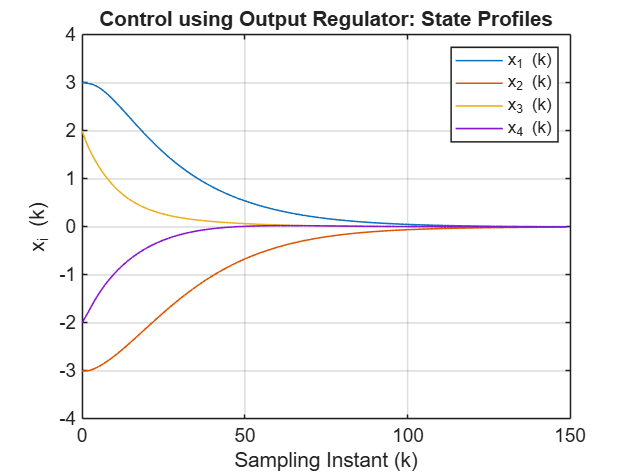

figure(4), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1 (k)', 'x_2 (k)', 'x_3 (k)', 'x_4 (k)'), title('Control using Output Regulator: State Profiles')

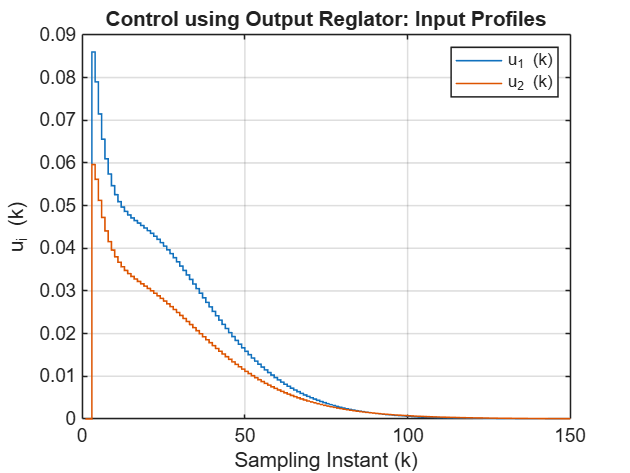

figure(5), stairs(uk', 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('u_i (k)'), title('Control using Output Reglator: Input Profiles')
legend('u_1 (k)', 'u_2 (k)')

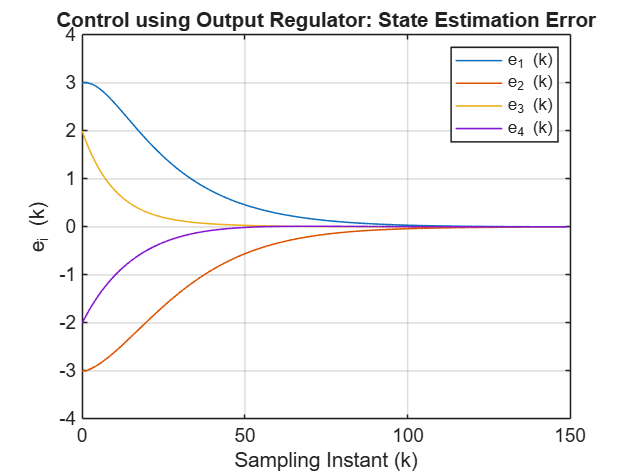

figure(6), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

Observe that the estimation errors have become zero and the states are brought to zero starting from any arbitrary initial states.

## Effect of Unmeasured** Disturbances**

If the process dynamics is influenced by nonzero unmeasured disturbances and $x\left(0\right)\not= \bar{0}$, then the system dynamics evolves as follows 

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)\\
y\left(k\right)=C\;x\left(k\right)
\end{array}$--------------------(8)

The state estimation error dynamics can be obtained by combining observer dynamics with equation (8) as follows 

$\varepsilon \left(k+1\right)=\left(\Phi -\textrm{LC}\right)\varepsilon \left(k\right)+\Gamma_d d\left(k\right)$-------------(9)

Note that in this case, the estimator **error does not decay to zero even when  **$\rho \left(\left(\Phi -L\;C\right)\right)<1$**, due to the presence of the term **$\Gamma_d d\left(k\right)$. Using equation (9) recursively, we can show that 

$\varepsilon \left(k\right)={\left(\Phi -\textrm{LC}\right)}^k \varepsilon \left(0\right)+\sum_{j=0}^{k-1} {\left(\Phi -LC\right)}^{k-j} {\;\;\Gamma }_d d\left(j\right)$  ------(10)

When $\rho \left(\left(\Phi -L\;C\right)\right)<1$, it follows that ${\left(\Phi -\textrm{LC}\right)}^k \to \left\lbrack 0\right\rbrack$ for large *k *and


$$\varepsilon \left(k\right)\to \sum_{j=0}^{k-1} {\left(\Phi -LC\right)}^{k-j} {\;\;\Gamma }_d d\left(j\right)$$


 With the state feedback controller, $u\left(k\right)=-G\;\hat{x} \left(k\right)$, the plant dynamics evolve as

$\begin{array}{l}
x\left(k+1\right)=\Phi x\left(k\right)-\Gamma G\left\lbrack x\left(k\right)-\varepsilon \left(k\right)\right\rbrack +\Gamma_d d\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=\left(\Phi -\Gamma G\right)x\left(k\right)+\Gamma G\varepsilon \left(k\right)+\Gamma_d d\left(k\right)
\end{array}$---------(11)

and  $x\left(k\right)$ **does not go to origin** even when $\rho \left(\Phi -\Gamma G\right)<1$, as the term 2 and 3 on RHS in equation (6) do not go to zero. 

## Effect of Model Plant Mismatch

If the controller is implemented on the real (nonlinear) system then the system dynamics are governed by 

$\begin{array}{l}
X\left(k+1\right)=F\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)\\
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;=F\left(x\left(k\right)+X_s ,u\left(k\right)+U_s ,d\left(k\right)+D_s \right)
\end{array}$  ------(12)

Defining

 $\delta F\left(x\left(k\right),u\left(k\right),d\left(k\right)\right)=F\left(x\left(k\right)+X_s ,u\left(k\right)+U_s ,d\left(k\right)+D_s \right)-X_s \;$  ----(13)

the nonlinear system dynamics can be expressed in terms of deviation variables as follows 

$x\left(k+1\right)=\delta F\left(x\left(k\right),u\left(k\right),d\left(k\right)\right)$ ------(14)

$y\left(k\right)=C\;x\left(k\right)$  ------(15)

Let us assume that the state is estimated using a linear state estimator 

$\hat{x\;} \left(k+1\right)=\Phi \hat{x\;} \left(k\right)+\Gamma u\left(k\right)+L\;e\left(k\right)$  -----(16) 

and the controller $u\left(k\right)=-G\hat{x\;} \left(k\right)$ is implemented on the nonlinear system

$x\left(k+1\right)=\delta F\left(x\left(k\right),-G\hat{x} \left(k\right),d\left(k\right)\right)=\delta F\left(x\left(k\right),-G\left(x\left(k\right)-\varepsilon \left(k\right)\right),d\left(k\right)\right)$  ------(17)

For the purpose of analysis, adding and subtracting $\left(\Phi -\Gamma G\right)x\left(k\right)$ on R.H.S. of equation (17) and rearranging, let us express the nonlinear system dynamics as follows 

$x\left(k+1\right)=\left(\Phi -\Gamma G\right)x\left(k\right)+g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)$  -------(18)

where 

$g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)=\delta F\left(x\left(k\right),-G\left(x\left(k\right)-\varepsilon \left(k\right)\right),d\left(k\right)\right)-\left(\Phi -\Gamma G\right)x\left(k\right)$  ------(19)

represents the plant model mismatch (MPM) signal. Since 

$e\left(k\right)=y\left(k\right)-C\hat{x} \left(k\right)=C\left(x\left(k\right)-\hat{x} \left(k\right)\right)=C\varepsilon \left(k\right)$  ------(20)

the observer evolves as

$\hat{x\;} \left(k+1\right)=\left(\Phi -\Gamma G\right)\hat{x} \left(k\right)+L\;C\varepsilon \left(k\right)$  -------(21)

Subtracting (12) from (11), the estimation error evolves as 

$\varepsilon \left(\left.k+1\right)=\left(\left(\Phi -\Gamma G\right)-L\;C\right)\varepsilon \left(k\right)+g\left(x\left(k\right),\varepsilon \left(k\right),d\left(k\right)\right)\right)$ --------(22)

Thus, the estimator error does not decay to zero even when $\rho \left(\Phi -L\;C\right)<1$ and $x\left(k\right)$ does not tend to the origin even when $\rho \left(\Phi -\Gamma G\right)<1$, because of the MPM term given by equation (19).

**Q Tank process Closed Loop Simulation with MPM and Disturbance**

global QTank U_k D_k
N = 551 ; 
xk = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [1 -1 1 -1]';
uk = zeros(n_ip,N) ;
dk = zeros(1,N) ;

**Task 4:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model. This results in plant model mismatch

Plant_Sim =1  ; 
%% 0 Nonlinear plant simulation 1: Linear plant simulation 

** Disturbance input **

Further we add disturbance input to the process. A time varying disturbance input signal is generated using **idinput** command in MATLAB

dk_prbs = 0.2 * idinput(401, 'rgs', [0.0 0.025] ) ;  
dk(151:end) = 0.4 + dk_prbs ; 
for k = 1:N-1
    kT(k) = (k-1);

    uk(:,k) = - G_inf * xkhat(:,k);
    ek = yk(:,k) - C_mat * xkhat(:,k) ;
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end

     % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam *uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k);  D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) ;

 end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results:Effect of Plant Model Mismatch**

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;

**Controlled output profiles **

figure, subplot(211), 
plot(kT, yk(1,:), 'b', kT, yk(2,:), 'k'), grid
title('Controlled Outputs (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Yk(2,:), 'k'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)',  'h_2 (k)',  'Orientation','horizontal','Location','Best')

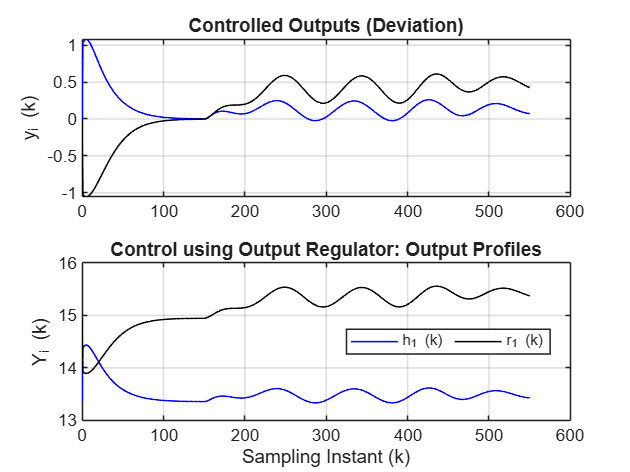

title('Control using Output Regulator: Output Profiles')

**Manipulated input profiles**

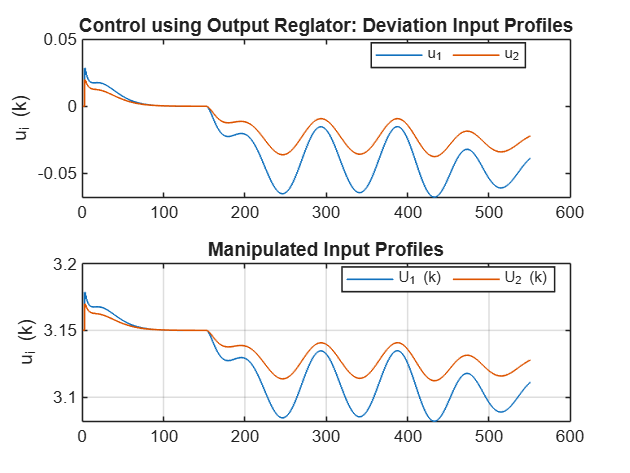

figure, subplot(211), 
stairs(uk', 'LineWidth',1)
ylabel('u_i (k)'), title('Control using Output Reglator: Deviation Input Profiles')
legend(  'u_1', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs( Uk', 'LineWidth',1),  grid
ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

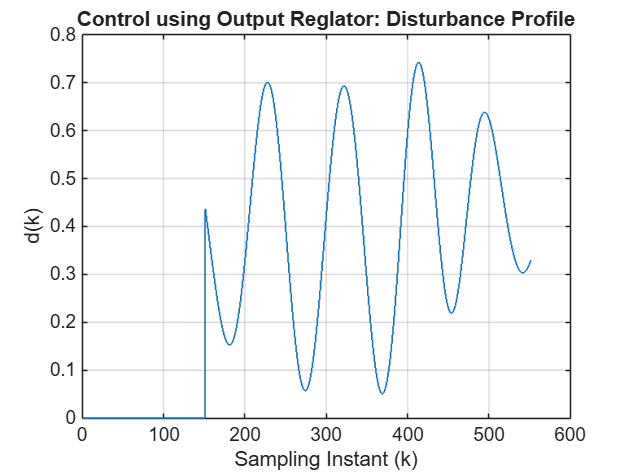

figure, stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Control using Output Reglator: Disturbance Profile')

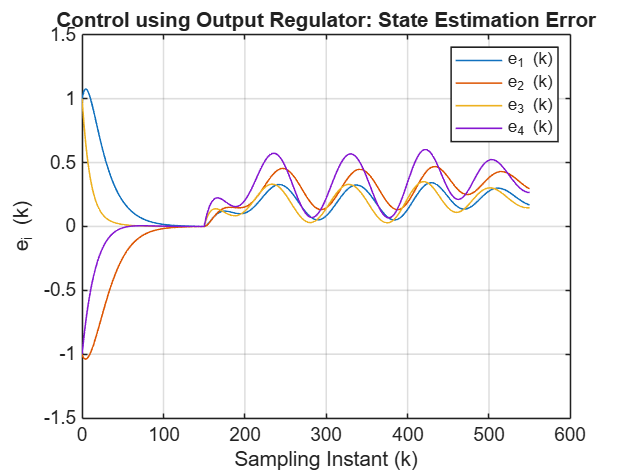

figure, plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

Thus, the state feedback regulator generates an offset if the unmeasured disturbances influencing state dynamics are non-stationary, i.e. they have slowly drifting behavior.

## Setpoint Tracking and Disturbance Rejection 

 If it is desired to achieve offset free control in the face of unmeasured disturbances or MPM or move the system from the equilibrium point to an arbitrary setpoint, then the [state feedback control law has to be further modified](matlab:open('./L04_OffsetFreeControl1.mlx')). In order to deal with such situations**, **it is necessary to introduce integral action in the controller. As discussed in Module 5, one method to achieve this is to modify the state state feedback control law using time varying target states and target inputs. In Module 5, we have computed target state state and target inputs using ***open loop observer, ***i.e. $L$ equals null matrix. We need to modify the target state computations now to account for the fact that a state estimator given by equation (2) is used as an internal model. The innovation signal, $e\left(k\right)=y\left(k\right)-C\hat{x\;} \left(k\right)$, contains information about unmeasured disturbances and MPM. Under the assumption that $e\left(k+j\right)=e\left(k\right)\;\textrm{for}\;j>k$, moving equilibrium point of the internal model can be found by solving for

${\widehat{x} }_s \left(k\right)=\Phi {\widehat{x} }_s \left(k\right)+\Gamma u_s \left(k\right)+L\;e\left(k\right)$   ------(23)

$y_s \left(k\right)=C{\widehat{x} }_s \left(k\right)+e\left(k\right)$   ------(24)

Eliminating ${\widehat{x} }_s \left(k\right)$ in equation (24) using

 $x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s \left(k\right)+\textrm{Le}\left(k\right)\right)$  ----(25)

we arrive at 

$\begin{array}{l}
y_s \left(k\right)=\left(C{\left(I-\Phi \right)}^{-1} \Gamma \right)\;u_s \left(k\right)+\left(I+C{\left(I-\Phi \right)}^{-1} L\right)\;e\left(k\right)\\
\;\;\;\;\;\;\;\;\;\;=\;G\;u_s \left(k\right)+G_e \;e\left(k\right)
\end{array}$ ------(26)

Setting $y_s \left(k\right)=r\left(k\right)$, when $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $u_s \left(k\right)={\left(G\right)}^{-1} \;\left(r\left(k\right)-G_e \;e\left(k\right)\right)$------(27)

When $u_s \left(k\right)$ computed using (27) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r\left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r\left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(28)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e\left(k\right)$ ------(29) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (30)

In either case, $x_s \left(k\right)$ can be found using equation (25). Using target states and target inputs, the control law is modified as follows 

$\begin{array}{l}
\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\Delta u\left(k\right)=-G\Delta x\left(k\right)\\
\Delta x\left(k\right)=x\left(k\right)-x_s \left(k\right)\;\;\textrm{and}\;\;\Delta u\left(k\right)=u\left(k\right)-u_s \;\left(k\right)
\end{array}$   -------(31)

 Thus, the state feedback control law that solves **servo and regulatory problems simultaneously **can be expressed as follows:

$u\left(k\right)=u_s \left(k\right)-G\left\lbrack x\left(k\right)-x_s \left(k\right)\right\rbrack$   ------(32)

N = 601 ; 
xk = zeros(n_st,N);
xs_k = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) =0.5*[1 -1 1 -1]';
uk = zeros(n_ip,N) ;
us_k = zeros(n_ip,N) ;
dk = zeros(1,N) ;
ek = zeros(n_op,N) ;

The gains $G\;\textrm{and}\;G_e \;$are then computed using equation (26), which are then used in the computation of target states and target inputs.

Gain_ss = C_mat * inv(eye(n_st)-phy)*gam ; 
Gain_e = eye(n_op) + C_mat * inv(eye(n_st)-phy)* L_inf ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero for $k<0$. It is changed such that $200\le k<400$ it 's magnitude is 0.5 and for $k>400$ it is 0.25

for k = 1:N
    if ( k < 200 )
        dk(k) = 0 ;
    elseif (k >= 200 ) && (k < 400)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 200
    else
        dk(k) = 0.25 ;  % Introduce another disturbance change at k = 400
    end
end
rk = zeros(n_op,1) ;

**Task 5:** Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model.

Plant_Sim =0  ; 

for k = 1:N-1
    kT(k) = (k-1);

     ek(:,k) = yk(:,k) - C_mat * xkhat(:,k) ;  
     us_k(:,k) = inv(Gain_ss) * ( rk - Gain_e * ek(:,k))  ;
     xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek(:,k))  ;

    uk(:,k) = us_k(:,k) - G_inf * (xkhat(:,k) - xs_k(:,k)) ;
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek(:,k) ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end

     % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k) ;  D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) ;

 end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results:Setpoint Tracking and Disturbance Rejection **

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk = rk+ C_mat * QTank.Xs ;
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;


**Controlled output profiles **

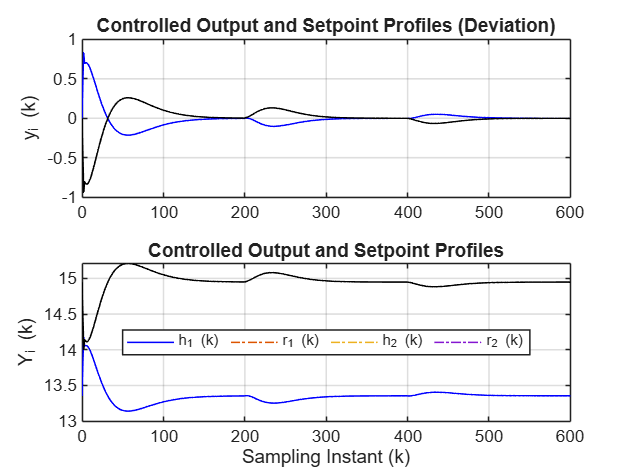

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk(1,:), '-.', kT, yk(2,:), 'k', kT, rk(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

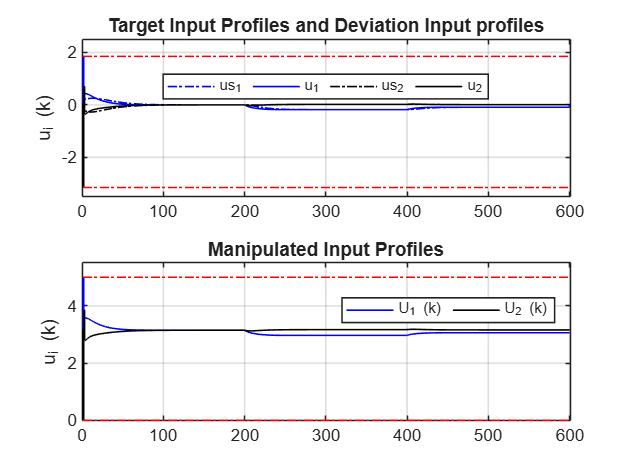

figure, subplot(211), stairs(kT, us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

** Disturbance input and Model Plant Mismatch profiles **

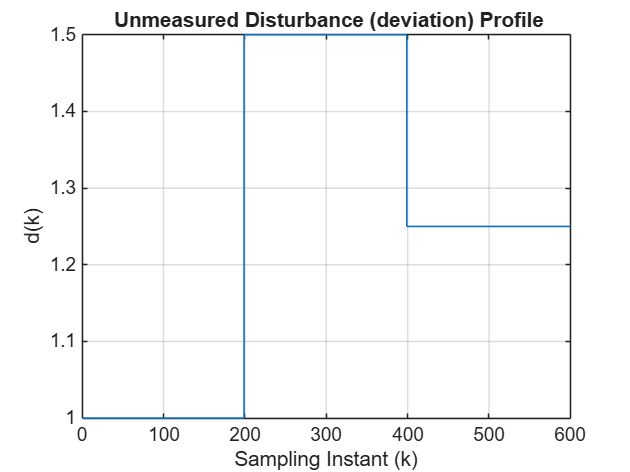

figure,  stairs( kT, Dk,'LineWidth',1 ), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)')
title(' Unmeasured Disturbance (deviation) Profile')

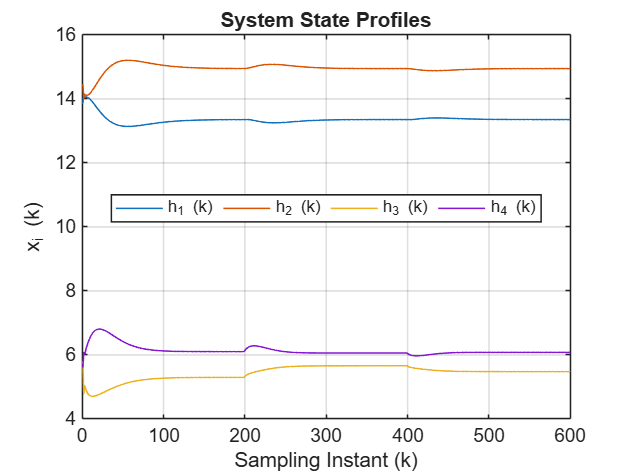


% System State profiles and MPC internal model profiles  
figure, plot(kT, Xk(1,:), kT, Xk(2,:), kT, Xk(3,:), kT, Xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('h_1 (k)', 'h_2 (k)', 'h_3 (k)', 'h_4 (k)', 'Orientation','horizontal','Location','Best')
title('System State Profiles')

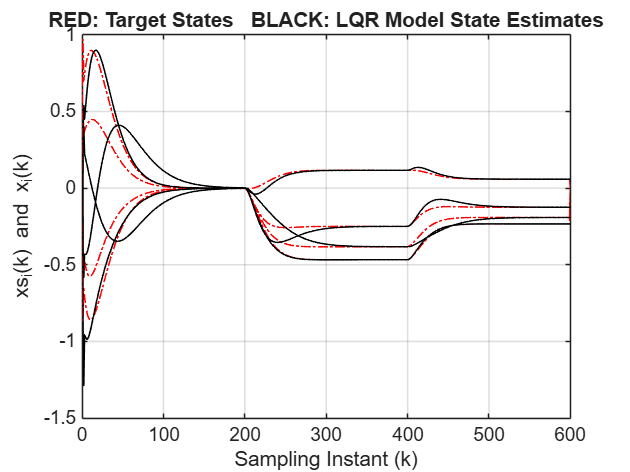

figure, plot(kT, xs_k, '-.r', kT, xkhat, 'k'), grid
title('RED: Target States   BLACK: LQR Model State Estimates')
xlabel('Sampling Instant (k)'), ylabel('xs_i(k) and x_i(k)')

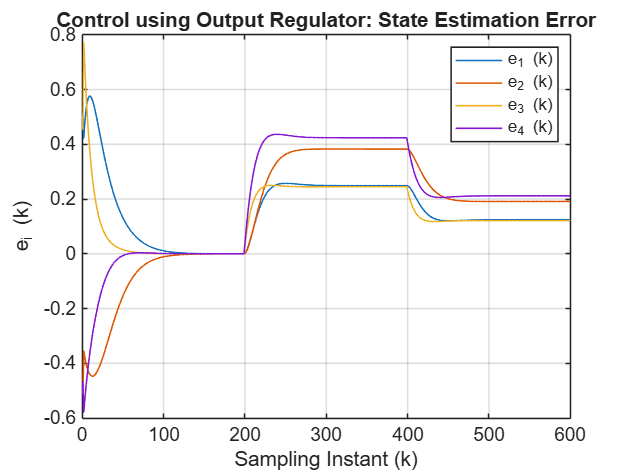

figure, plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
 xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
 legend('e_1 (k)', 'e_2 (k)', 'e_3 (k)', 'e_4 (k)'), title('Control using Output Regulator: State Estimation Error')

**Task 6: **Repeat the exercise for linear plant simulation. Observe that the perturbation outputs of the regulator are tracked to zero in the presence of disturbances. 

### Innovation Filter

When the measurements are corrupted with zero mean random noise and disturbance input is also corrupted with zero mean noise, the innovation signal has significant high frequency component, which can result in undesirable oscillations in the manipulated inputs. The low frequency drifting mean of $\left\lbrace e\left(k\right)\right\rbrace$can be estimated using a simple unity gain first order filter of the form

$\begin{array}{l}
e_f \left(k\right)=\Phi_e e_f \left(k-1\right)+\left(I-\Phi_e \right)e\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\alpha_1  & \alpha_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \alpha_1 
\end{array}\right\rbrack 
\end{array}$  ------(33)

where  $0\le \alpha_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters.  Choice of this parameter influences the regulatory (disturbance rejection) behavior of the LQG controller. Similarly, the setpoint changes can be introduced by filtering through low pass unity gain filter to avoid sudden changes in the manipulated inputs. 

$\begin{array}{l}
r_f \left(k+1\right)=\Phi_r r_f \left(k\right)+\left(I-\Phi_r \right)r\left(k\right)\\
\Phi_e =\textrm{diag}\left\lbrack \begin{array}{cccc}
\beta_1  & \beta_2  & \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp  & \beta_r 
\end{array}\right\rbrack 
\end{array}$  ------(34)

where  $0\le \beta_i \le 1\;\;\;\;\;i=1,2\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp r$ are the tuning parameters. Here we demonstrate the effect of innovation filtering on the closed loop behavior. The target state and input calculations are modified using these filtered signals as follows: 

When $l=m$, we can derive expression for $u_s \left(k\right)$ as follows 

 $u_s \left(k\right)={\left(G\right)}^{-1} \;\left(r_f \left(k\right)-G_e \;e_f \left(k\right)\right)$------(35)

When $u_s \left(k\right)$ computed using (27) is outside the input bounds, or when $l\not= m$, the target state can be computed by solving $u_s \left(k\right)$ can be found by solving the following optimization problem

$\min_{u_s \left(k\right)} \left\lbrace {\left(r_f \left(k\right)-y_s \left(k\right)\right)}^T \;W_{\textrm{ys}} \left(r_f \left(k\right)-y_s \left(k\right)\right)\right\rbrace$   ------(36)

subject to,

$y_s \left(k\right)=G\;u_s \left(k\right)+G_e \;e_f \left(k\right)$ ------(37) 

$u^L \le u_s \left(k\right)\le u^H$ ------ (38)

After solving the optimization problem the target state, $x_s \left(k\right)$, can be found using equation 

$x_s \left(k\right)={\left(I-\Phi \right)}^{-1} \left(\Gamma u_s \left(k\right)+L{\mathrm{e}}_f \left(k\right)\right)$   ------(39)

### **Control Using Output Regulator with Innovation Filter**

We now add the innovation filter and observe the closed loop behaviour of the controller.

 
N = 651 ; 
xk = zeros(n_st,N);
xs_k = zeros(n_st,N);
yk = zeros(n_op,N) ;
est_err = zeros(n_st,N); 
xkhat = zeros(n_st,N);
xk(:,1) = [1 -1 1 -1]';
uk = zeros(n_ip,N) ;
us_k = zeros(n_ip,N) ;
dk = zeros(1,N) ;
ek = zeros(n_op,N) ;
ek_f = zeros(n_op,N) ;

**Task 7: **Set alfa_d value to 0 to see effect of noise on u(k). Innovation filter is designed using this parameter.

alfa_d =0.85;  % Set this value to 0 to see effect of noise on u(k) 
phy_d = alfa_d * eye(n_op) ;  % Innovation filter 

**Task 8:** To run the closed loop simulations with Innovation Filter Set innovation_filter_on to 1

innovation_filter_on = 1 ;
rk_f = zeros(n_op,N);     % Setpoint filter parameters 
beta_r = 0.95 ;  % Set this value to 0 see effect of step change in rk on u(k)
phy_r = beta_r * eye(n_op) ; % 

 Generate state and measurement noise sequences 

**Task 9:** Set the value of Noise_ON to 1 to introduce white noise disturbances  

Noise_ON=1% Set this value to 1 to introduce white noise disturbances  

Noise_ON = 1

wk = mvnrnd(zeros(n_d,1), Q_mat, N) ;
wk = Noise_ON * wk' ;
vk = mvnrnd(zeros(n_op,1), R_mat, N) ;
vk = Noise_ON * vk' ;

** Disturbance input **

A time varying disturbance input signal is generated such that initially it is set to zero for $k<0$. It is changed such that $200\le k<400$ it 's magnitude is 0.5 and for $k>400$ it is 0.25

for k = 1:N
    if ( k < 200 )
        dk(k) = 0 ;
    elseif (k >= 200 ) && (k < 400)
        dk(k) = 0.5 ;  % Introduce disturbance change at k = 200
    else
        dk(k) = 0.25  ;  % Introduce another disturbance change at k = 400
    end
end

dk = dk + [zeros(1, 200) wk(201:end) ] ; 

rk = zeros(n_op,1) ;

**Task 10: **Select Plant_Sim as Nonlinear for simulating Q Tank process using a nonlinear ODE model.

Plant_Sim =0  ;

for k = 1:N-1
    kT(k) = (k-1);

     ek(:,k) = yk(:,k) - C_mat * xkhat(:,k) ;  
     ek_f(:,k+1) = phy_d * ek_f(:,k) + (eye(n_op) - phy_d) * ek(:,k) ; 

     % Setpoint change introduced simultaneously with the disturbance
     % change at k = 400
     if (k >= 400),   rk = [ 3 -3 ]';  end  
     rk_f(:,k+1) = phy_r * rk_f(:,k) + (eye(n_op) - phy_r) * rk   ; 

     if (innovation_filter_on )
         us_k(:,k) = inv(Gain_ss) * ( rk_f(:,k+1) - Gain_e * ek_f(:,k))  ;
         xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek_f(:,k))  ;
     else
         us_k(:,k) = inv(Gain_ss) * ( rk - Gain_e * ek(:,k))  ;
         xs_k(:,k) = inv(eye(n_st) - phy) * ( gam * us_k(:,k) + L_inf * ek(:,k))  ;
     end

    uk(:,k) = us_k(:,k) - G_inf * (xkhat(:,k) - xs_k(:,k)) ;
    xkhat(:,k+1) = phy * xkhat(:,k) + gam * uk(:,k) + L_inf * ek(:,k) ;
    est_err(:,k) = xk(:,k) - xkhat(:,k) ;

    if ( uk(1,k) <= u_L(1) )   % Impose input constraints on uk(1)
        uk(1,k) = u_L(1) ;
    elseif ( uk(1,k) >= u_H(1) )
        uk(1,k) = u_H(1) ;
    end
    if ( uk(2,k) <= u_L(2) ) % Impose output constraints on uk(2)
        uk(2,k) = u_L(2) ;
    elseif ( uk(2,k) >= u_H(2) )
        uk(2,k) = u_H(2) ;
    end

     % Quadruple tank Plant Simulation from k to k+1

    if (Plant_Sim )
        xk(:,k+1) = phy * xk(:,k) + gam * uk(:,k) + gam_d * dk(k)  ;
    else
        U_k = QTank.Us + uk(:,k) ;  D_k =  QTank.Ds + dk(k)  ;
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 QTank.samp_T ], QTank.Xs+xk(:,k)) ;   % Nonlinear plant simulation
        xk(:,k+1) = Xt( end,: )' - QTank.Xs ;
    end
    yk(:,k+1) = C_mat * xk(:,k+1) + vk(:,k+1);  %Measurement with noise 

 end
uk(:,N) = uk(:,N-1) ;
est_err(:,N) =  est_err(:,N-1) ;
ek(:,N) = ek(:,N-1) ;
kT(N) = N-1 ; 

**Simulation Results**

Xk = QTank.Xs + xk ;   Uk = QTank.Us + uk ; Dk = QTank.Ds + dk ;
Yk = yk + C_mat * QTank.Xs ;  Rk_f = rk_f + C_mat * QTank.Xs ;
u_limit = [u_L(1)*ones(N,1) u_H(1)*ones(N,1)]  ;

**Controlled output profiles **

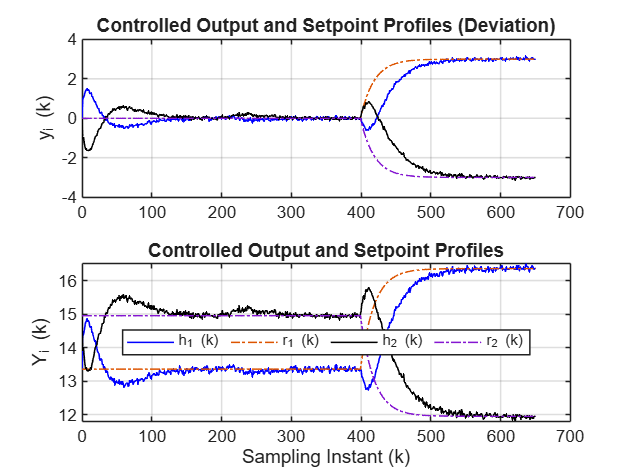

figure, subplot(211), 
plot(kT, yk(1,:), 'b',  kT, rk_f(1,:), '-.', kT, yk(2,:), 'k', kT, rk_f(2,:), '-.'), grid
title('Controlled Output and Setpoint Profiles (Deviation)'), ylabel('y_i (k)')
subplot(212), plot(kT, Yk(1,:), 'b',  kT, Rk_f(1,:), '-.', kT, Yk(2,:), 'k', kT, Rk_f(2,:), '-.'), grid
xlabel('Sampling Instant (k)'), ylabel('Y_i (k)')
legend('h_1 (k)', 'r_1 (k)', 'h_2 (k)', 'r_2 (k)', 'Orientation','horizontal','Location','Best')
title('Controlled Output and Setpoint Profiles')

**Manipulated input profiles**

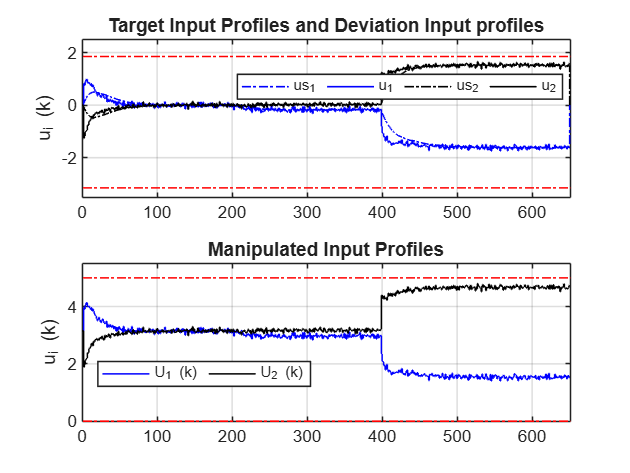

figure, subplot(211), stairs(kT, us_k(1,:)', '-.b','LineWidth',1), grid
hold on
stairs(kT, uk(1,:)', 'b','LineWidth',1)
stairs(kT, us_k(2,:)', '-.k','LineWidth',1)
stairs(kT, uk(2,:)', 'k','LineWidth',1)
stairs(u_limit, '-.r', 'LineWidth',1)
axis([0 N -3.5 2.5])
hold off
ylabel('u_i (k)'), title('Target Input Profiles and Deviation Input profiles')
legend( 'us_1', 'u_1', 'us_2', 'u_2', 'Orientation','horizontal','Location','Best')
subplot(212), stairs(kT, Uk(1,:)', 'b','LineWidth',1),  grid
hold on, stairs(kT, Uk(2,:)', 'k','LineWidth',1),
stairs(u_limit+QTank.Us', '-.r', 'LineWidth',1), hold off
axis([0 N 0 5.5]), ylabel('u_i (k)')
title('Manipulated Input Profiles')
legend( 'U_1 (k)', 'U_2 (k)','Orientation','horizontal','Location','Best')

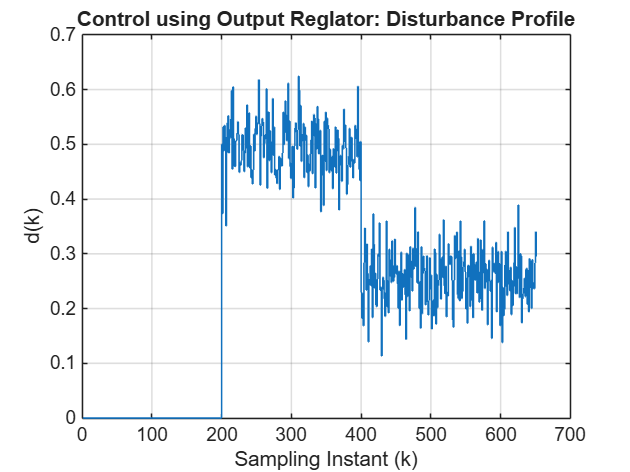

figure, stairs(dk, 'LineWidth',1), grid
xlabel('Sampling Instant (k)'), ylabel('d(k)'), title('Control using Output Reglator: Disturbance Profile')

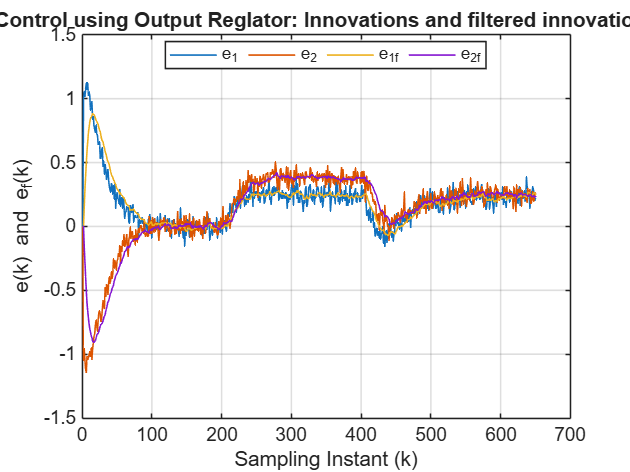

figure, plot(ek', 'LineWidth',1), grid
hold on 
plot(ek_f', 'LineWidth',1)
hold off 
xlabel('Sampling Instant (k)'), ylabel('e(k) and e_f(k)')
legend('e_1', 'e_2', 'e_1_f', 'e_2_f', 'Orientation','horizontal','Location','Best')
title('Control using Output Reglator: Innovations and filtered innovations')

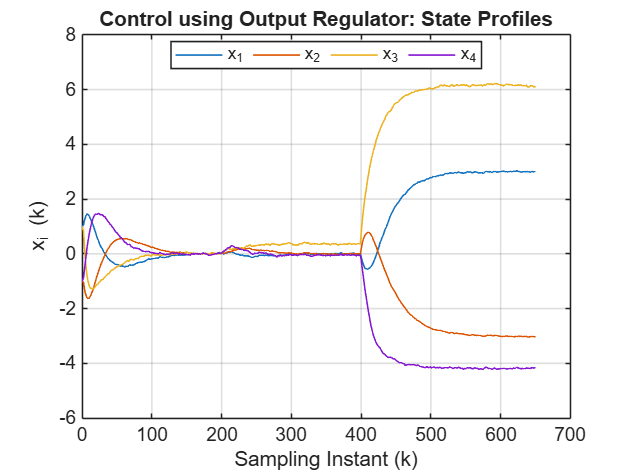

figure(20), plot(kT, xk(1,:), kT, xk(2,:), kT, xk(3,:), kT, xk(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('x_i (k)')
legend('x_1', 'x_2', 'x_3', 'x_4' , 'Orientation','horizontal','Location','Best'), 
title('Control using Output Regulator: State Profiles')

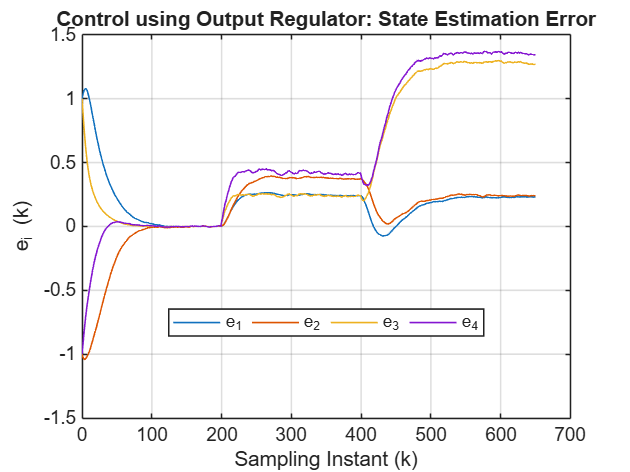

figure(21), plot(kT, est_err(1,:), kT, est_err(2,:), kT, est_err(3,:), kT, est_err(4,:)), grid
xlabel('Sampling Instant (k)'), ylabel('e_i (k)')
legend('e_1', 'e_2', 'e_3', 'e_4', 'Orientation','horizontal','Location','Best'), 
title('Control using Output Regulator: State Estimation Error')

**Task 11: **Now set alfa_d to maximum value and observe the inputs. They are now quite smooth. 

**Task 12: **Now run the simulation, without innovation filter. Note the bias in the outputs. 

**Task 13:** Now you can make the noise zero and observe the outputs. They still have a bias. Make the innovation filter ON again

**Task 14: **Repeat the exercise for nonlinear plant simulation

As evident from this simulation exercise, fluctuations in the manipulated inputs reduce significantly when innovation signal is filtered using a unity gain filter. The last figure shows that the innovation signal reduces to a zero mean white noise signal (between instant 100 to 200) where there is no unmeasured disturbance or MPM. However, the innovation signal becomes biased (non-zero mean) when the drifting unmeasured disturbance is introduced (for k > 200) or PMM is additionally introduced when plant dynamics are simulated using nonlinear ODEs. The filtered innovation captures the drifting mean of the innovations, which needs to be dealt with for achieving offset fee control through computation of target states an target inputs.  

## Conclusions 

State feedback controllers have to be implemented using states estimated using observers that combine measurements with model predictions. Use of a state estimator allows us to implement a state feedback control law on an unstable system as evident from the CSTR case study. Further, to deal with drifting unmeasured disturbances and MPM, the control laws need to be modified using moving state and input targets to achieve offset free control. 